### PART B

% STEP 1: define variables r and theta
N = 10000000;
r = rand(N,1);
theta = 2*pi*rand(N,1);

% STEP 2: convert to cartesian coordinates
x= sqrt(r).*cos(theta);
y= sqrt(r).*sin(theta);

% STEP 3: scale x,y to give ellipse
major_axis=1;
minor_axis=2;
x=(major_axis/2).*x;
y=(minor_axis/2).*y;

% STEP 4: plot

histogram2(x,y,'DisplayStyle','tile')

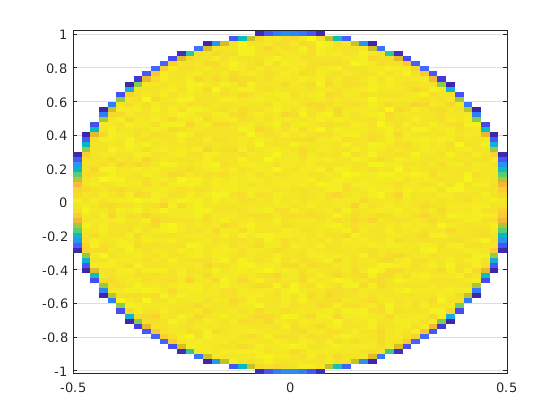

saveas(gcf,sprintf('ellipse1.png'));

### PART D

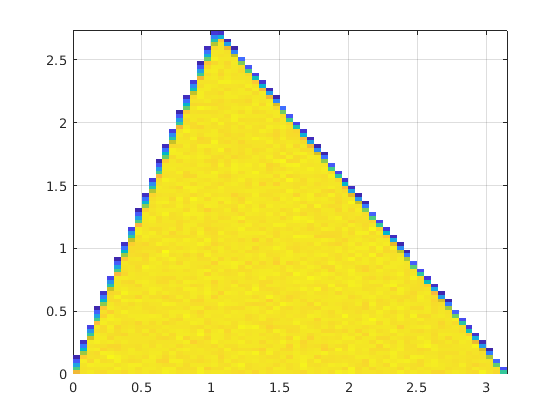

% STEP 1: define a and b
P1=[0  0];
P2=[pi 0];
P3=[pi/3 exp(1)];
a= P3-P1;
b= P2-P1;

% STEP 2: define random uniform variable u1 and u2
N=10000000;
u1=rand(N,1);
u2=rand(N,1);

% STEP 3: reflect along diagonal
for i = 1:N
    if(u1(i)+u2(i)>1)
        u1(i)=1-u1(i);
        u2(i)=1-u2(i);
    end
end

% STEP 4: plot
x=u1.*a(1) + u2.*b(1);
y=u1.*a(2) + u2.*b(2);
histogram2(x,y,'DisplayStyle','tile')
saveas(gcf,sprintf('triangle1.png'));